# LAB5 MATLAB Programming

涂峻绫(12213010) and 欧阳安男(12211831)

## Introduction

MATLAB is a powerful tool to ......

## Results and Analysis

### 1

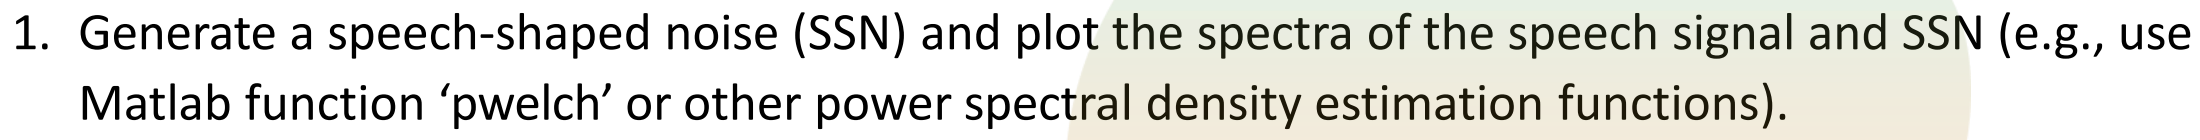

Load audio.

clear;clc;
[x, fs] = audioread('lab5/C_01_02.wav');
x = x';

Generate white noise.

whitenoise = 1-2*rand(1,length(x));

Generate long-term spectrum of speech signal to estimate the power spectral density of the speech signal.

sig = repmat(x,1,10);
[Pxx,f] =pwelch(sig, [], [], 512, fs);

Generate filter coefficients.

b = fir2(3000,f/(fs/2),sqrt(Pxx/max(Pxx)));

Perform filtering for white noise signal to get the SSN.

ssn = filter(b,1,whitenoise);

Get the spectra of the signal and SSN.

X = fftshift(fft(x)) / fs;
SSN = fftshift(fft(ssn)) / fs;
omega = linspace(-pi,pi,length(X));

Plot the spectra of the signal and SSN.

figure;
subplot(2,1,1);
plot(omega,X);

title('the spectra of the signal');
xlabel('\omega');
ylabel('X(j\omega)');
xticks(-pi:pi/2:pi);
xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});
subplot(2,1,2);
plot(omega,SSN);

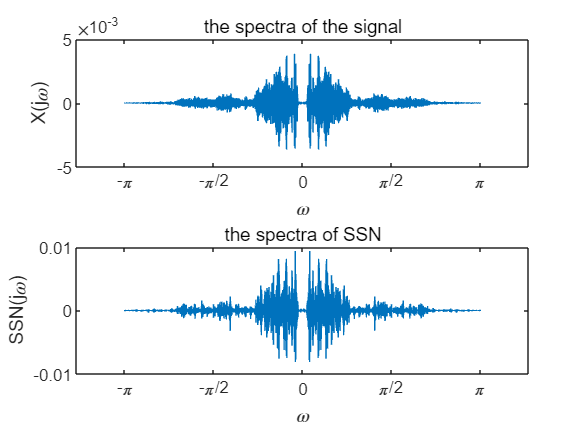

title('the spectra of SSN');
xlabel('\omega');
ylabel('SSN(j\omega)');
xticks(-pi:pi/2:pi);
xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});

### 2

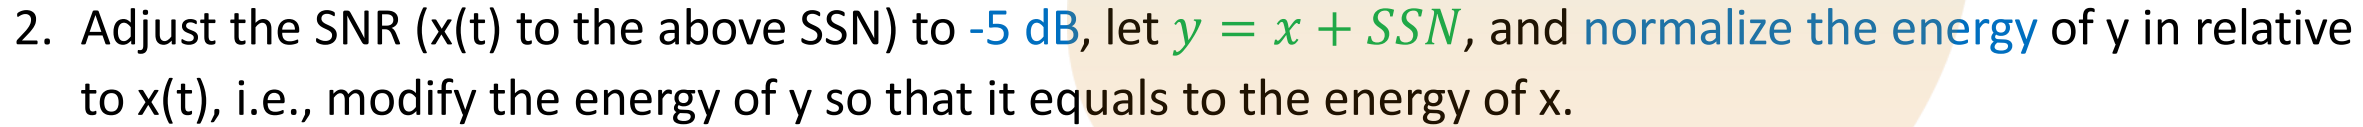

Adjust SNR.

X2 = X / sqrt(10);
x2 = ifft(ifftshift(X2)) * fs;

Generate y.

y = x2 + ssn;

Modify y.

y = y*norm(x2)/norm(y);
norm(y)==norm(x2)

ans = logical
   1


Get the spectra of y.

Y = fftshift(fft(y)) / fs;

Plot the spectra of the adjusted SNR and y.

figure;
subplot(2,1,1);
plot(omega,X2);

title('the spectra of adjusted SNR');
xlabel('\omega');
ylabel('X_2(j\omega)');
xticks(-pi:pi/2:pi);
xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});
subplot(2,1,2);
plot(omega,Y);

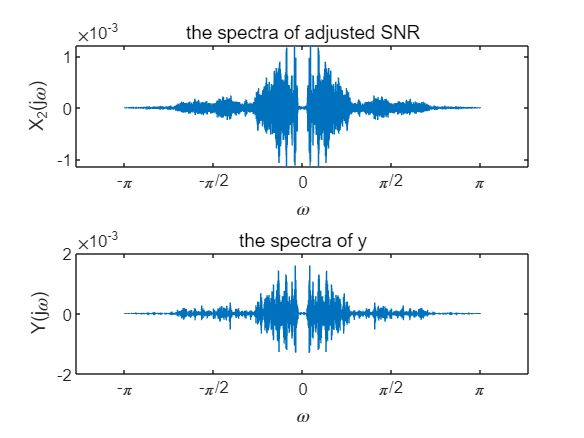

title('the spectra of y');
xlabel('\omega');
ylabel('Y(j\omega)');
xticks(-pi:pi/2:pi);
xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'});

### 3

#### 1)

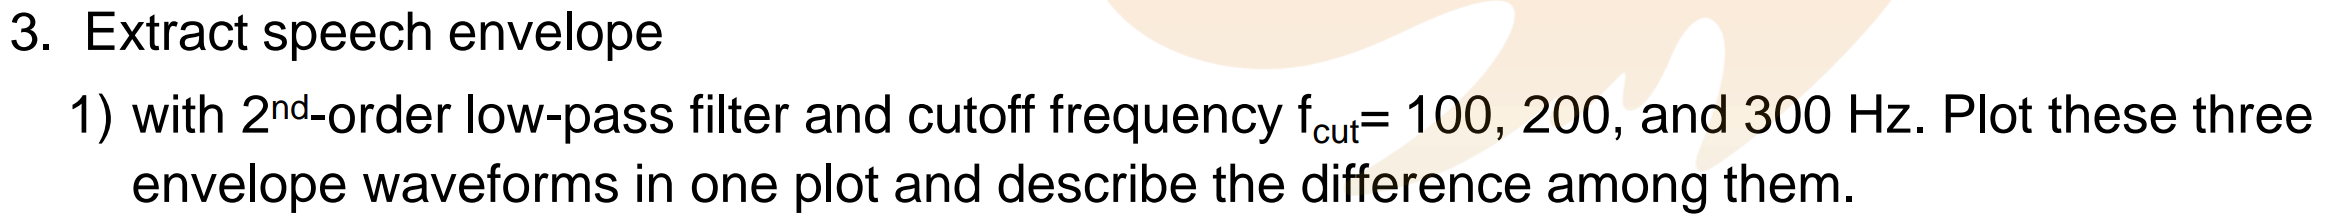

#### 2)

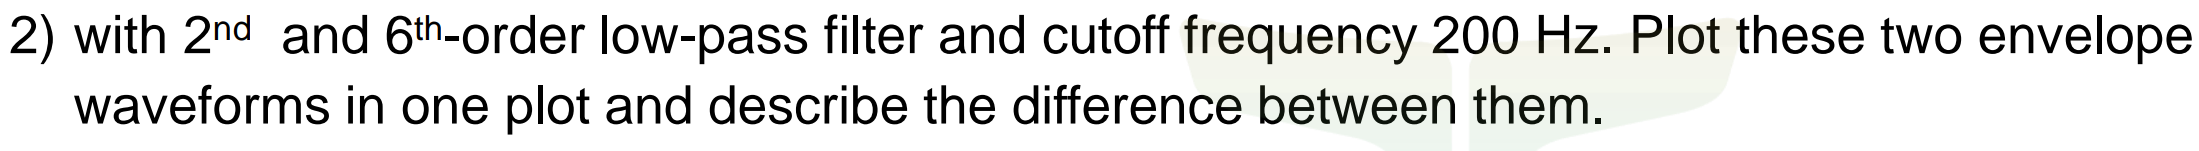

### Functions

## Expeience

........................